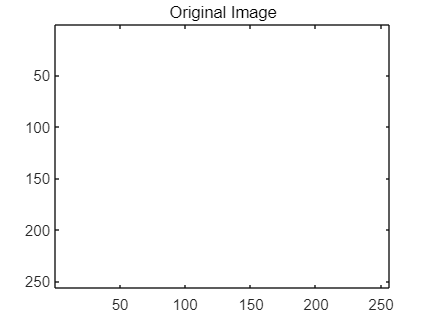

% 创建一个256x256x3的数组，每个颜色通道初始化为1
a = ones(256, 256, 3);
image(a);
title('Original Image');

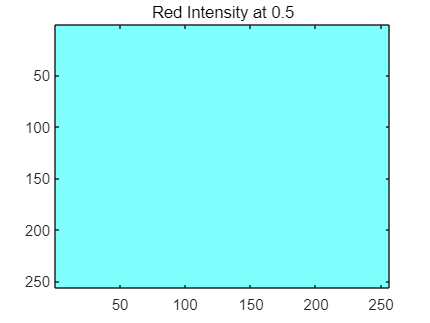


% 修改红色通道
a_red = a;
a_red(:,:,1) = 0.5; 
figure; 
image(a_red);
title('Red Intensity at 0.5');

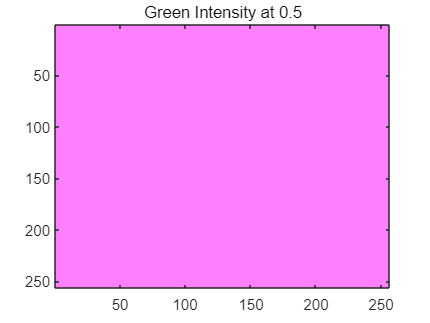

% 修改绿色通道
a_green = a;
a_green(:,:,2) = 0.5; 
figure;
image(a_green);
title('Green Intensity at 0.5');

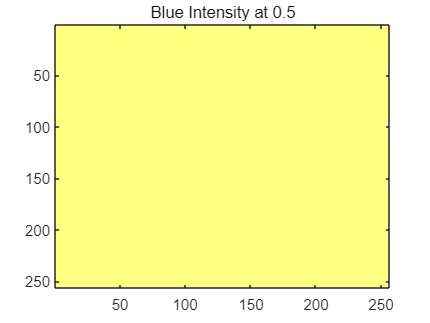

% 修改蓝色通道
a_blue = a;
a_blue(:,:,3) = 0.5; 
figure;
image(a_blue);
title('Blue Intensity at 0.5');

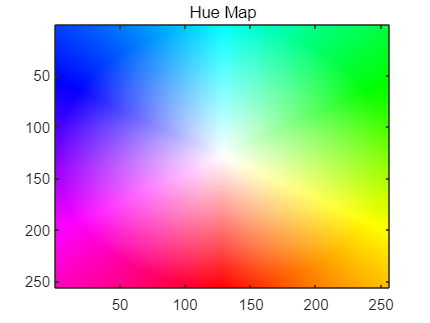


% 创建HSB色彩空间的色调映射并显示:
% 创建一个圆形的色调映射
[xx, yy] = ndgrid(linspace(-1, 1, 256), linspace(-1, 1, 256));
hh = atan2(yy, xx); 
hh = mod(hh/(2*pi), 1); 
ss = sqrt(xx.^2 + yy.^2); 
ss(ss > 1) = 1; % 限制饱和度最大为1
bb = ones(size(ss)); % 亮度设为最大值1
% 将HSB转换为RGB
hue_map = hsv2rgb(cat(3, hh, ss, bb));
% 显示色调映射
figure;
image(hue_map);
title('Hue Map');

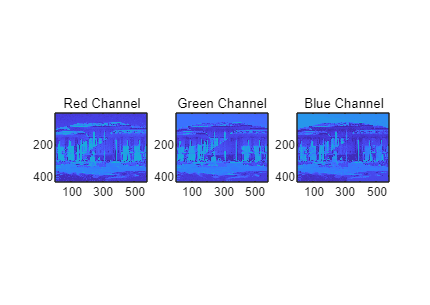

clc;

% 读取红色通道图像
filenamer = 'lab10prob2r';
fileID = fopen(filenamer, 'rb'); 
imagedata_r = fread(fileID, [580, 435], 'uint8'); 
fclose(fileID);  
subplot(1, 3, 1); 
image(imagedata_r');
axis('image');
title('Red Channel');

% 读取绿色通道图像
filenameg = 'lab10prob2g';
fileID1 = fopen(filenameg, 'rb'); 
imagedata_g = fread(fileID1, [580, 435], 'uint8'); 
fclose(fileID1);  
subplot(1, 3, 2);
image(imagedata_g');
axis('image');
title('Green Channel');

% 读取蓝色通道图像
filenameb = 'lab10prob2b';
fileID2 = fopen(filenameb, 'rb'); 
imagedata_b = fread(fileID2, [580, 435], 'uint8');
fclose(fileID2);  
subplot(1, 3, 3);
image(imagedata_b');
axis('image');
title('Blue Channel');

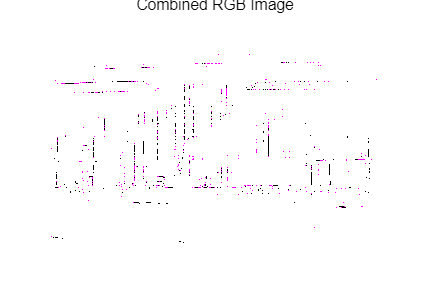


% 合并三个通道
colorImage = cat(3, imagedata_r', imagedata_g', imagedata_b');

colorImage = imadjust(colorImage, stretchlim(colorImage), []);

figure; 
imshow(colorImage);
title('Combined RGB Image');

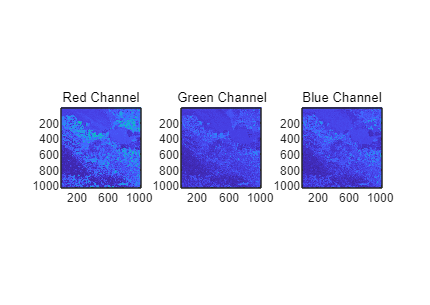

% 读取红色通道图像
filenamer = 'lab10prob3r';
fileID = fopen(filenamer, 'rb'); 
imagedata_r = fread(fileID, [1024, 1024], 'uint8'); 
fclose(fileID);  
subplot(1, 3, 1); 
image(imagedata_r');
axis('image');
title('Red Channel');

% 读取绿色通道图像
filenameg = 'lab10prob3g';
fileID1 = fopen(filenameg, 'rb'); 
imagedata_g = fread(fileID1, [1024, 1024], 'uint8'); 
fclose(fileID1);  
subplot(1, 3, 2);
image(imagedata_g');
axis('image');
title('Green Channel');

% 读取蓝色通道图像
filenameb = 'lab10prob3b';
fileID2 = fopen(filenameb, 'rb'); 
imagedata_b = fread(fileID2, [1024, 1024], 'uint8');
fclose(fileID2);  
subplot(1, 3, 3);
image(imagedata_b');
axis('image');
title('Blue Channel');

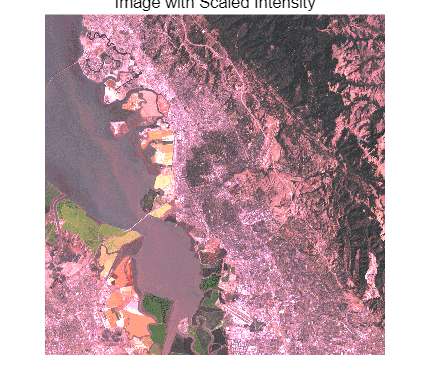

imageData = cat(3, imagedata_r, imagedata_g, imagedata_b);


meanTotal = mean(imageData(:));
stdTotal = std(double(imageData(:)));

targetMean = 140;
targetStd = 60;

scaledImageData = (double(imageData) - meanTotal) / stdTotal * targetStd + targetMean;
scaledImageData(scaledImageData < 0) = 0;
scaledImageData(scaledImageData > 255) = 255;
scaledImageData = uint8(scaledImageData);

figure;
imshow(scaledImageData);
title('Image with Scaled Intensity');

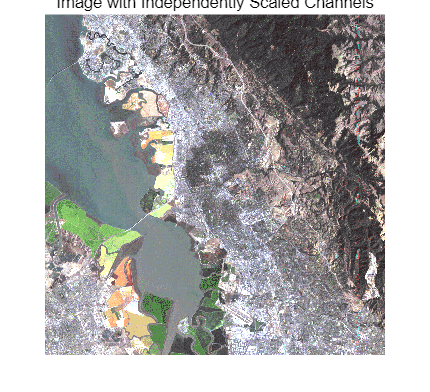


scaledChannels = imageData;
for channel = 1:3
    channelMean = mean(mean(imageData(:,:,channel)));
    channelStd = std(double(imageData(:,:,channel)), 0, 'all');
    
    scaledChannels(:,:,channel) = (double(imageData(:,:,channel)) - channelMean) / channelStd * targetStd + targetMean;
end

scaledChannels(scaledChannels < 0) = 0;
scaledChannels(scaledChannels > 255) = 255;
scaledChannels = uint8(scaledChannels);

figure;
imshow(scaledChannels);
title('Image with Independently Scaled Channels');

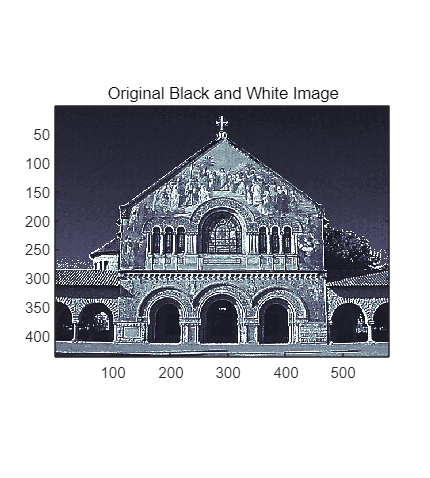

filenamer = 'lab10prob4data';
fileID = fopen(filenamer, 'rb'); 
imagedata = fread(fileID, [580, 435], 'uint8'); 
fclose(fileID);  
image(imagedata');
axis('image');
title('Original Black and White Image');

colormap('bone'); 

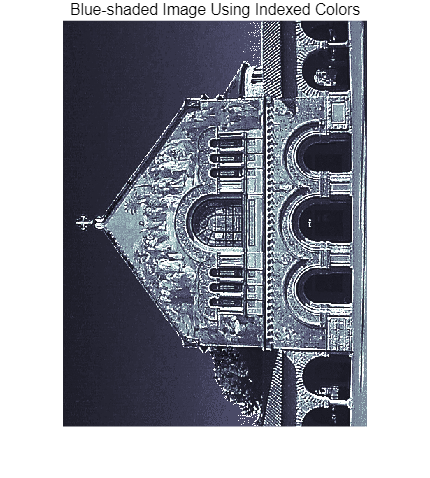

colorImage = ind2rgb(imagedata, colormap);
figure;
imshow(colorImage);
title('Blue-shaded Image Using Indexed Colors');

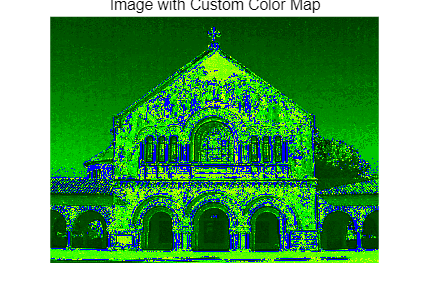


newColorMap = zeros(256, 3);

newColorMap(1:101, 2) = linspace(0, 1, 101);
newColorMap(101:201, 1) = linspace(0, 1, 101);
newColorMap(101:201, 2) = 1;

newColorMap(201:256, 3) = linspace(1, 1, 56);


figure;
imshow(imagedata', []);
colormap(newColorMap);
title('Image with Custom Color Map');


imwrite(lab10prob4data, newColorMap, 'customColoredImage.png');

函数或变量 'lab10prob4data' 无法识别。

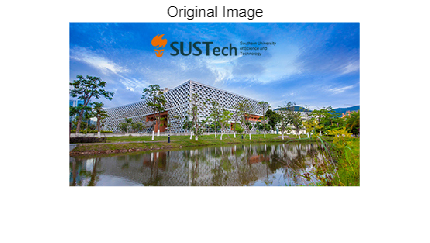

imagePath = 'testImage.jpg'; 
originalImage = imread(imagePath);
figure;
imshow(originalImage);
title('Original Image');

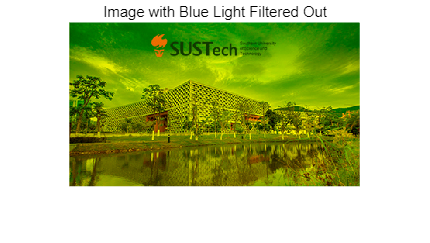


noBlueImage = originalImage;
noBlueImage(:,:,3) = 0;
figure;
imshow(noBlueImage);
title('Image with Blue Light Filtered Out');

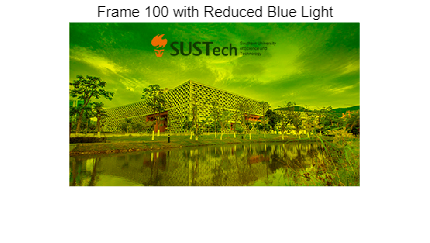


numFrames = 100;
M(numFrames) = struct('cdata',[],'colormap',[]); 
v = VideoWriter('FluxFade', 'MPEG-4');
v.FrameRate = 25;
open(v);

for k = 1:numFrames
    blueIntensity = uint8(double(noBlueImage(:,:,3)) * (1 - (k-1)/numFrames));
    transitionImage = originalImage;
    transitionImage(:,:,3) = blueIntensity;
    
    imshow(transitionImage);
    title(sprintf('Frame %d with Reduced Blue Light', k));
    
    M(k) = getframe(gcf);
    
    writeVideo(v, M(k));
end

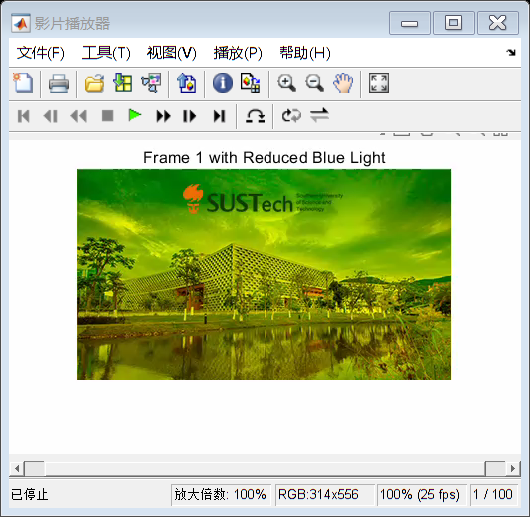


close(v);

videoFile = 'FluxFade.mp4';
implay(videoFile);